##  DEATH


clearvars
clc
close all
load("/Users/sebastianzinn/PowerFolders/Death_EEG/Enzephalopathie Tod/Matlabfiles/EEG_struct_death.mat")


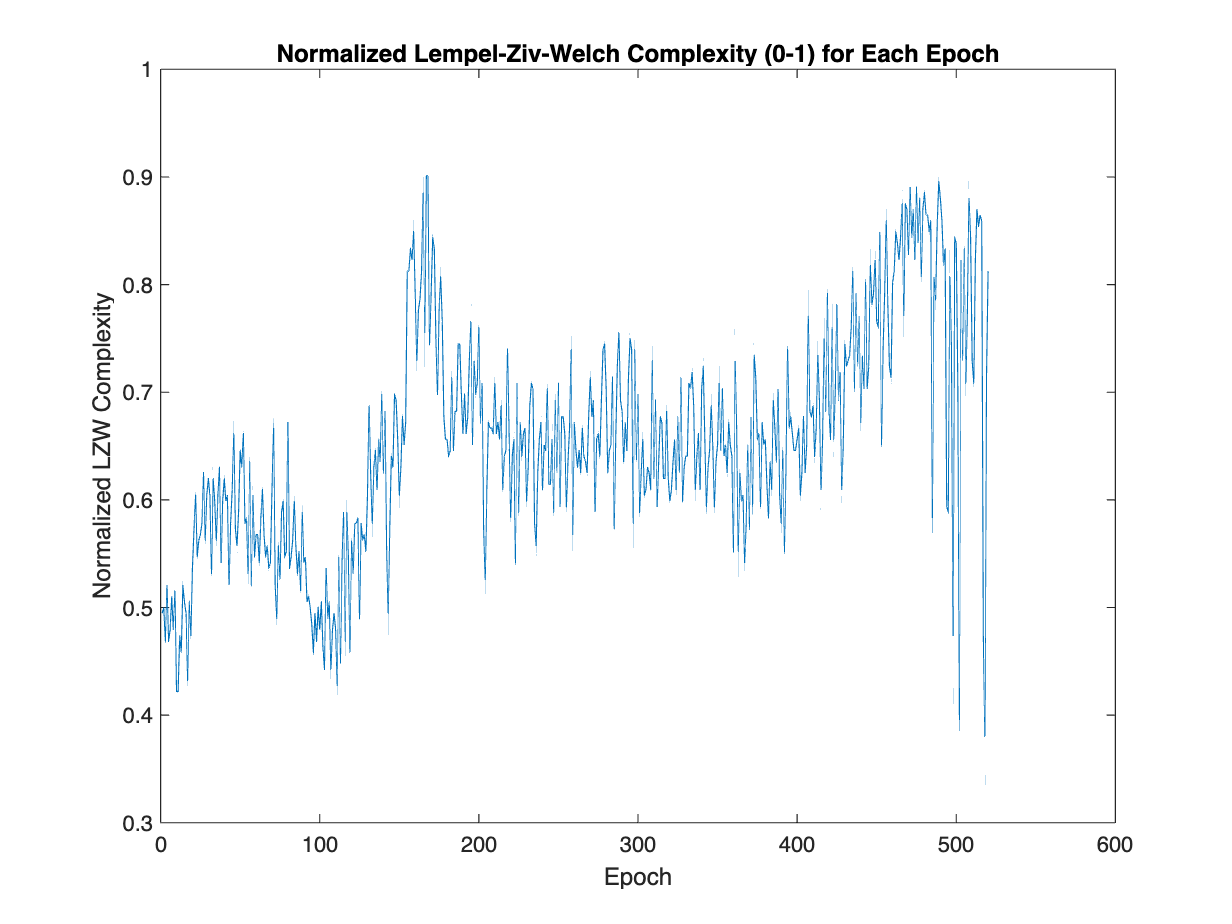

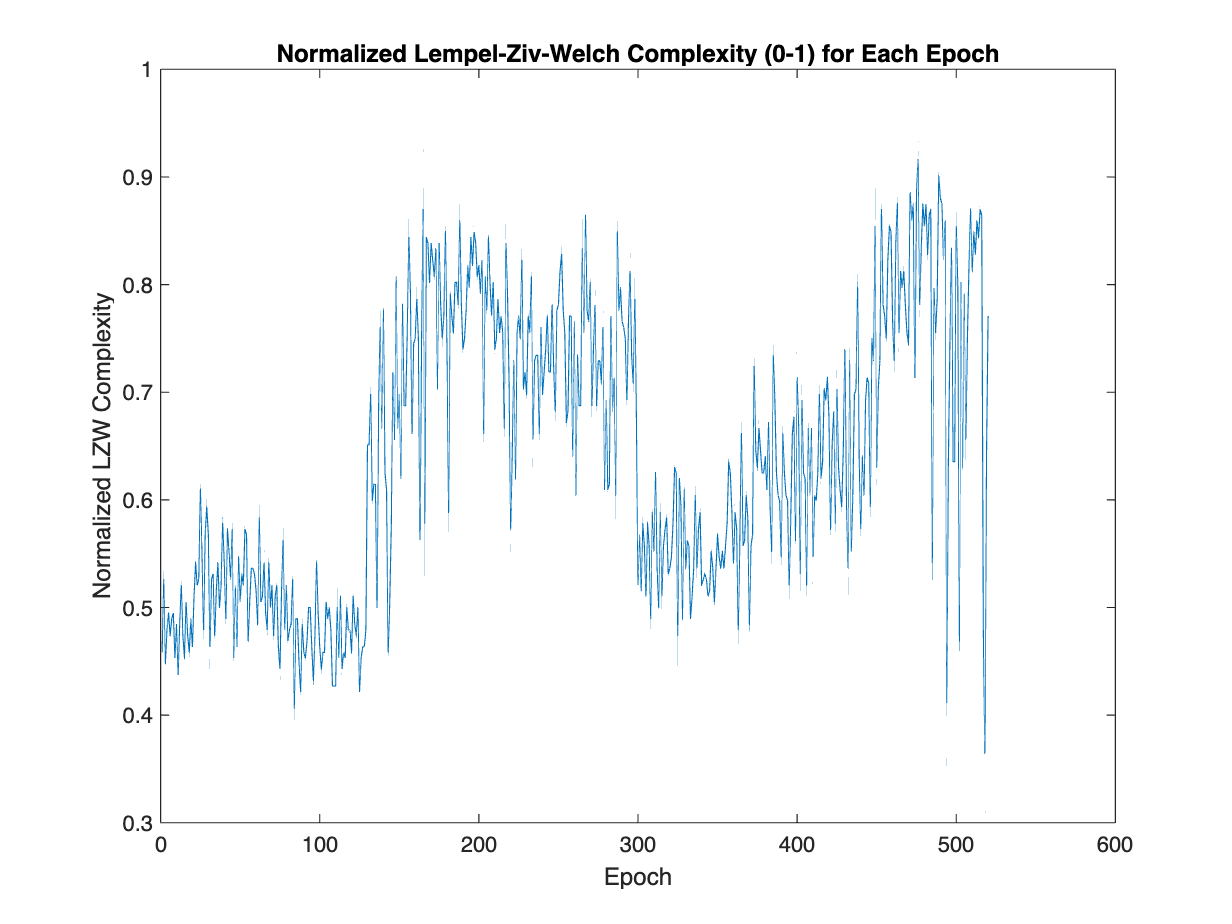

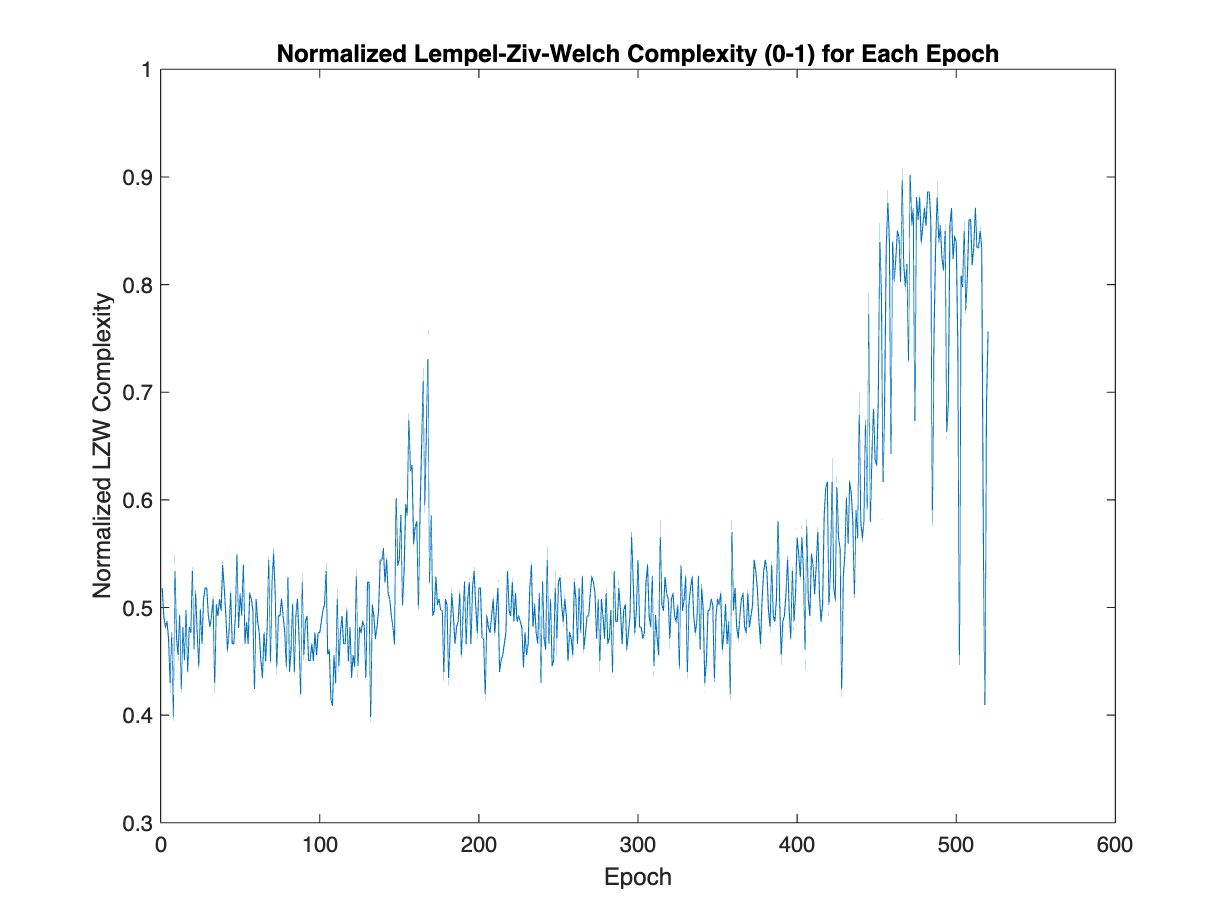

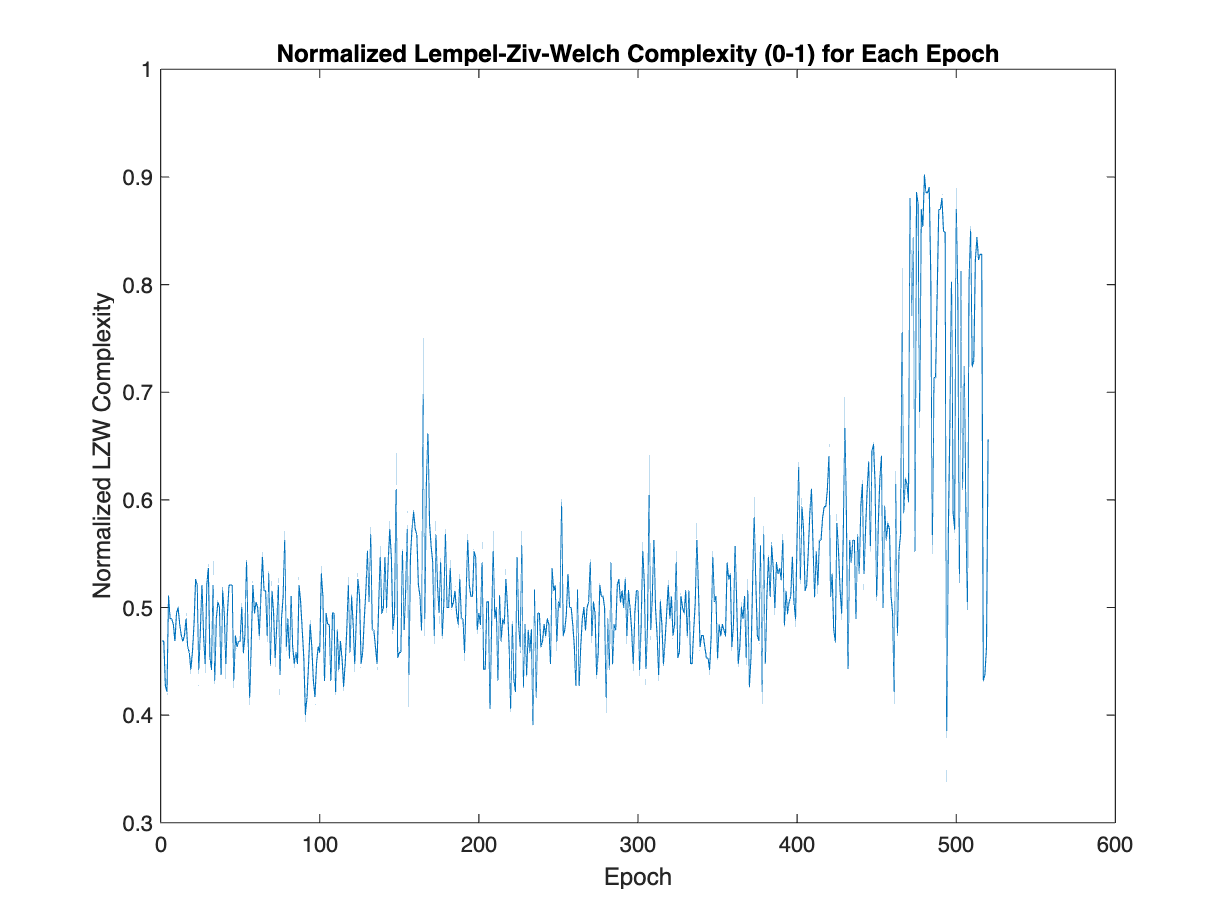

sr = 178.1538461538462;
fs=sr;
% Filter signal settings
low_cutoff = 0.5; % Low cut-off frequency for high-pass filter
high_cutoff = 45; % High cut-off frequency for low-pass filter

% Design the filters
[b_high, a_high] = butter(2, low_cutoff / (fs / 2), 'high');
[b_low, a_low] = butter(2, high_cutoff / (fs / 2), 'low');



clear buf
for i = 1:4
    buf = EEG.data(i,:);
    buf = filtfilt(b_high, a_high, buf);
    buf = filtfilt(b_low, a_low, buf);
    EEG.data(i,:) = buf;
    clear buf
end

%down sample to 128 Hz.
tempeeg(1,:) = resample(EEG.data(1,:),7185,10000);
tempeeg(2,:) = resample(EEG.data(2,:),7185,10000);
tempeeg(3,:) = resample(EEG.data(3,:),7185,10000);
tempeeg(4,:) = resample(EEG.data(4,:),7185,10000);


[PSD(:,:,1), ~] = calculate_PSD_shift(tempeeg(1,:),128,256,10,5);
[PSD(:,:,2), ~] = calculate_PSD_shift(tempeeg(2,:),128,256,10,5);
[PSD(:,:,3), ~] = calculate_PSD_shift(tempeeg(3,:),128,256,10,5);
[PSD(:,:,4), freq] = calculate_PSD_shift(tempeeg(4,:),128,256,10,5);

bis(1,:) = openibis(tempeeg(1,:)');
bis(2,:) = openibis(tempeeg(2,:)');
bis(3,:) = openibis(tempeeg(3,:)');
bis(4,:) = openibis(tempeeg(4,:)');

% Initialize LZC matrix
    lwz = [];
    for i =1:4
    lwz(i,:) = calculate_eeg_lzw_complexity(tempeeg(i,:), 128,7.5);
    end

% Initialize permutation matrix
    pem_EN = [];
    for i = 1:size(tempeeg, 1)
        [PeEn npe probdist] = calculate_PeEn_shift_hist (tempeeg(i,:), 128,7.5, 5);
        pem_EN(i, :) = npe;
        clear pe npe probdist
    end



teeg = linspace(0,65,length(tempeeg(1,:)))-59.5;
tpsd = linspace(0,65,length(PSD(1,:,1)))-59.5;
tbis = linspace(0,65,length(bis(1,:)))-59.5;
tlwz = linspace(0,65,length(lwz(1,:)))-59.5;
tpem = linspace(0,65,length(pem_EN(1,:)))-59.5;


locs = [EEG.chanlocs.labels];


fooof_settings = struct('peak_width_limits',[1,6],'max_n_peaks',3,'min_peak_height',0.3); 

for j = 1:4
    j
for i = 1:size(PSD,2) 
channel(j).fooof_results(i) = fooof(freq,PSD(:,i,j),[1 45],fooof_settings,1);
end
end

j = 1

j = 2

j = 3

j = 4



for j = 1:4
    temp1 = [];
    temp2 = [];
for i = 1:numel(channel(1).fooof_results)
    % Extract the aperiodic_params vector from the struct
    aperiodic_params_vector = channel(j).fooof_results(i).aperiodic_params;
    
    % Extract the first and second entries and append them to respective vectors
    temp1 = [temp1; aperiodic_params_vector(1)];
    temp2 = [temp2; aperiodic_params_vector(2)];
end
offset(:,j) = temp1;    
exponent(:,j) = temp2;
    
    clear temp1 temp2
end

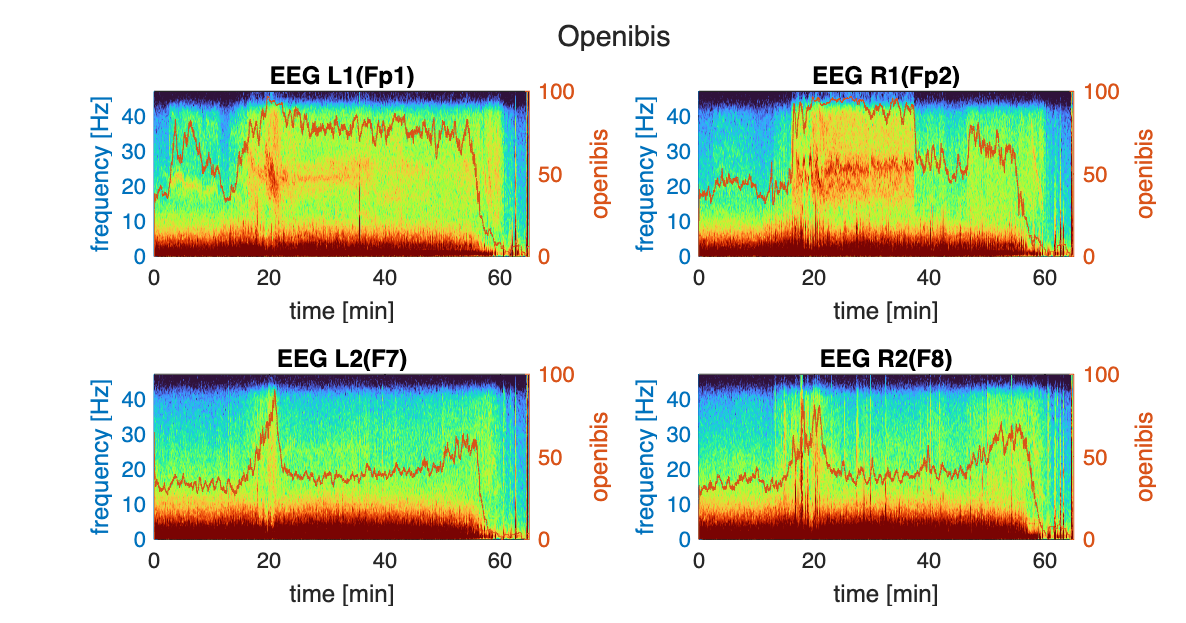

figure('Name','Parameters','Units','centimeters','Position', [0 0 19 10]);
tcl = tiledlayout(2,2);

sgtitle('Openibis')
for i = 1:4
nexttile(i)
title(EEG.chanlocs(i).labels)
yyaxis left
  pcolor(tpsd,freq,10*log10(PSD(:,:,i))); 
   clim([-35 3])
   ylabel 'frequency [Hz]'
   xlabel 'time [min]'
   colormap turbo
   shading flat
   shading interp
   ylim ([0 47])
yyaxis right
   plot(tbis,bis(i,:))
   ylabel 'openibis'
   ylim ([0 100])
end

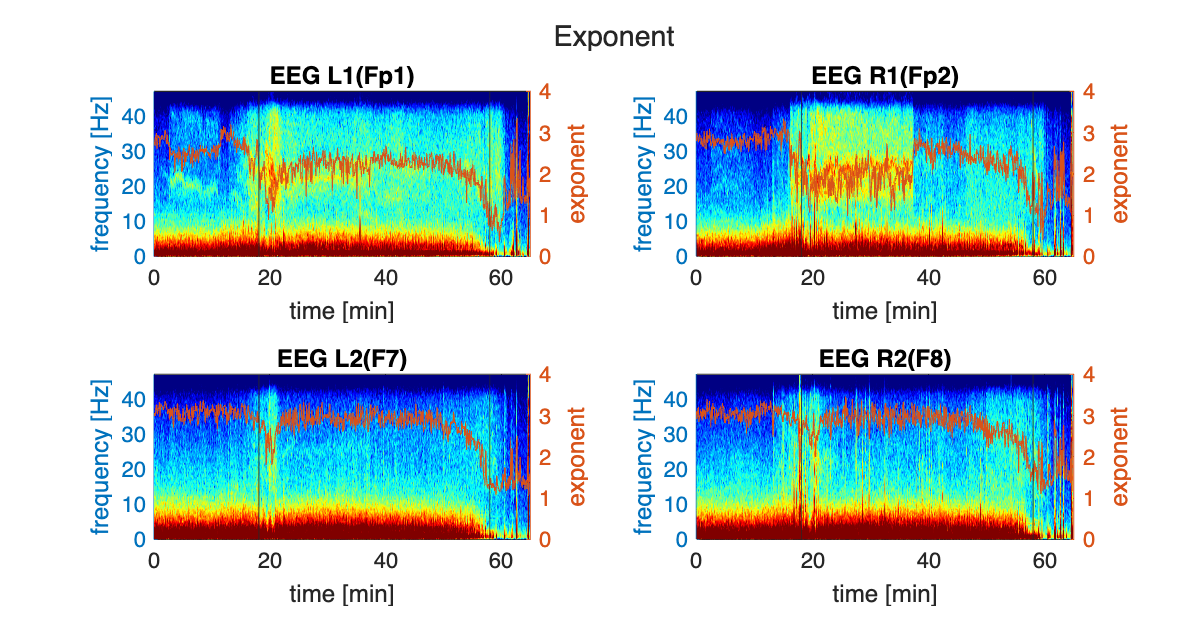

figure('Name','Parameters','Units','centimeters','Position', [0 0 19 10]);
tcl = tiledlayout(2,2);

tw18 = 18.1117;   % in min from start 
tw56 = 58;          % time point to choos before death

sgtitle('Exponent')
for i = 1:4
nexttile(i)
title(EEG.chanlocs(i).labels)
yyaxis left
  pcolor(tpsd,freq,10*log10(PSD(:,:,i))); 
   clim([-35 3])
   ylabel 'frequency [Hz]'
   xlabel 'time [min]'
   shading interp;
   colormap(jet);
   caxis([-30, 5]);
   shading interp
   ylim ([0 47])
yyaxis right
   plot(tpsd,exponent(:,i))
   ylabel 'exponent'
    ylim ([0 4])
xline(tw18)
xline(tw56)
end

FOOOF_Results = readtable('/Users/sebastianzinn/PowerFolders/Death_EEG/Enzephalopathie Tod/Matlabfiles/FOOF_sumery3.csv');
baseline = 5; %base line before therapy stop;
idx_baseline = find(tpsd > baseline,2);
FOOOF_Results.Exponent(1:4) = mean(exponent(idx_baseline:(idx_baseline+25),:),1)'

FOOOF_Results = 41×5 table
       Zeitpunkt        Category      Exponent     offset     Channel
    _______________    ___________    ________    ________    _______

    {'baseline'   }    {'death 0'}     2.4582       1.1517    {'Fp1'}
    {'baseline'   }    {'death 0'}      2.748       1.3235    {'Fp2'}
    {'baseline'   }    {'death 0'}     3.0235       1.8982    {'F7' }
    {'baseline'   }    {'death 0'}     3.0264       1.8839    {'F8' }
    {'minus 18min'}    {'death 1'}     2.0768       1.0196    {'Fp1'}
    {'minus 18min'}    {'death 1'}     1.7021      0.81567    {'Fp2'}
    {'minus 18min'}    {'death 1'}     2.8997       1.8141    {'F7' }
    {'minus 18min'}    {'death 1'}     2.9011       1.9056    {'F8' }
    {'minus 3min' }    {'death 2'}    0.84355     -0.85217    {'Fp1'}
    {'minus 3min' }    {'death 2

FOOOF_Results.offset(1:4) = mean(offset(idx_baseline:(idx_baseline+25),:),1)'

FOOOF_Results = 41×5 table
       Zeitpunkt        Category      Exponent     offset     Channel
    _______________    ___________    ________    ________    _______

    {'baseline'   }    {'death 0'}     2.4582       1.1517    {'Fp1'}
    {'baseline'   }    {'death 0'}      2.748       1.3235    {'Fp2'}
    {'baseline'   }    {'death 0'}     3.0235       1.8982    {'F7' }
    {'baseline'   }    {'death 0'}     3.0264       1.8839    {'F8' }
    {'minus 18min'}    {'death 1'}     2.0768       1.0196    {'Fp1'}
    {'minus 18min'}    {'death 1'}     1.7021      0.81567    {'Fp2'}
    {'minus 18min'}    {'death 1'}     2.8997       1.8141    {'F7' }
    {'minus 18min'}    {'death 1'}     2.9011       1.9056    {'F8' }
    {'minus 3min' }    {'death 2'}    0.84355     -0.85217    {'Fp1'}
    {'minus 3min' }    {'death 2


tw18 = 22.1117;   % in min from start 
idx_tw18 = find(tpsd > tw18,1)

idx_tw18 = 267

FOOOF_Results.Exponent(5:8) = mean(exponent(idx_tw18:(idx_tw18+25),:),1)';
FOOOF_Results.offset(5:8) = mean(offset(idx_tw18:(idx_tw18+25),:),1)';

idx_tw56 = find(tpsd > tw56,1)

idx_tw56 = 697

FOOOF_Results.Exponent(9:12) = mean(exponent(idx_tw56:(idx_tw56+25),:),1)';
FOOOF_Results.offset(9:12) = mean(offset(idx_tw56:(idx_tw56+25),:),1)';

writetable(FOOOF_Results, '/Users/sebastianzinn/PowerFolders/Death_EEG/Enzephalopathie Tod/Matlabfiles/FOOF_sumery3.csv');

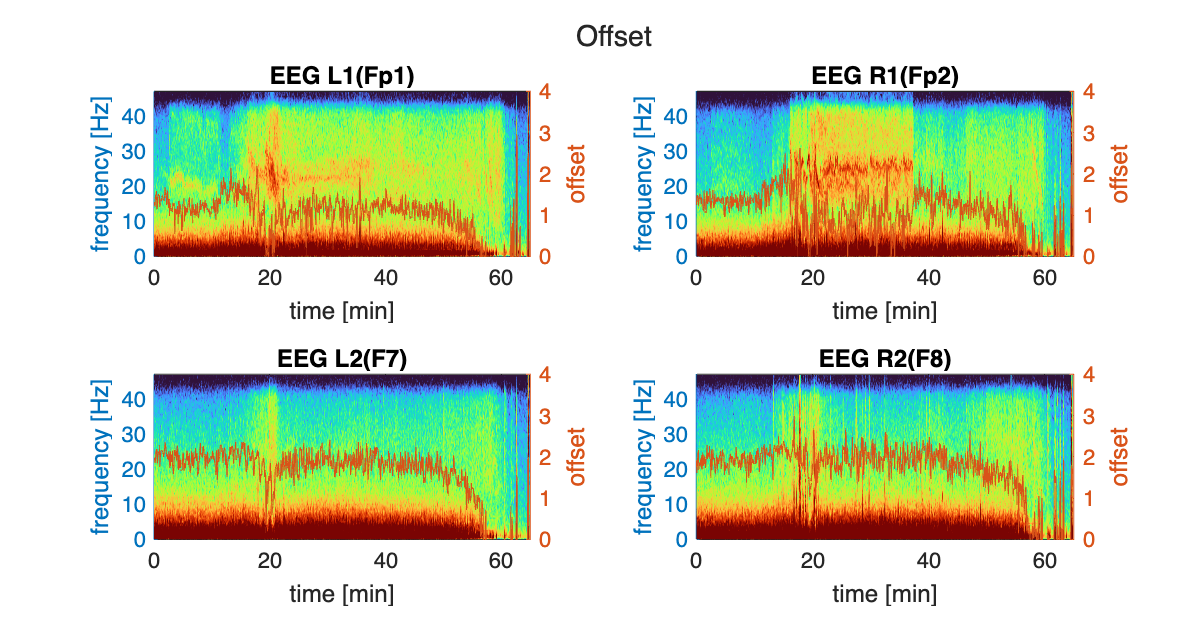

figure('Name','Parameters','Units','centimeters','Position', [0 0 19 10]);
tcl = tiledlayout(2,2);

sgtitle('Offset')
for i = 1:4
nexttile(i)
title(EEG.chanlocs(i).labels)
yyaxis left
  pcolor(tpsd,freq,10*log10(PSD(:,:,i))); 
   clim([-35 3])
   ylabel 'frequency [Hz]'
   xlabel 'time [min]'
   colormap turbo
   shading flat
   shading interp
   ylim ([0 47])
yyaxis right
   plot(tpsd,offset(:,i))
   ylabel 'offset'
    ylim ([0 4])
end


%% 
% 
figure('Name','Parameters','Units','centimeters','Position', [0 0 19 10]);

tcl = tiledlayout(2,2);

sgtitle('Complexity over time')
for i = 1:4
nexttile(i)

title(EEG.chanlocs(i).labels)
yyaxis left
  pcolor(tpsd,freq,10*log10(PSD(:,:,i))); 
   clim([-35 3])
   ylabel 'frequency [Hz]'
   xlabel 'time [min]'
   colormap jet
   shading flat
   shading interp
   ylim ([0 47])
yyaxis right
   h1 = plot(tlwz,lwz(i,:),"Color",'w','LineWidth',2);
   hold on
   h2 = plot(tpem,pem_EN(i,:),"Color",'r','LineWidth',2);
   hold off
   ylabel 'LWZ/PeEn'
   ylim ([0 1])
   if i ==4
    legend([h1 h2], {'LWZ', 'PeEn'},"BackgroundAlpha",0.5,"Box","off" , 'Position',[0.89 0.45 0.1 0.1]);
   else
       x=1
   end
  
end

x = 1

x = 1

x = 1

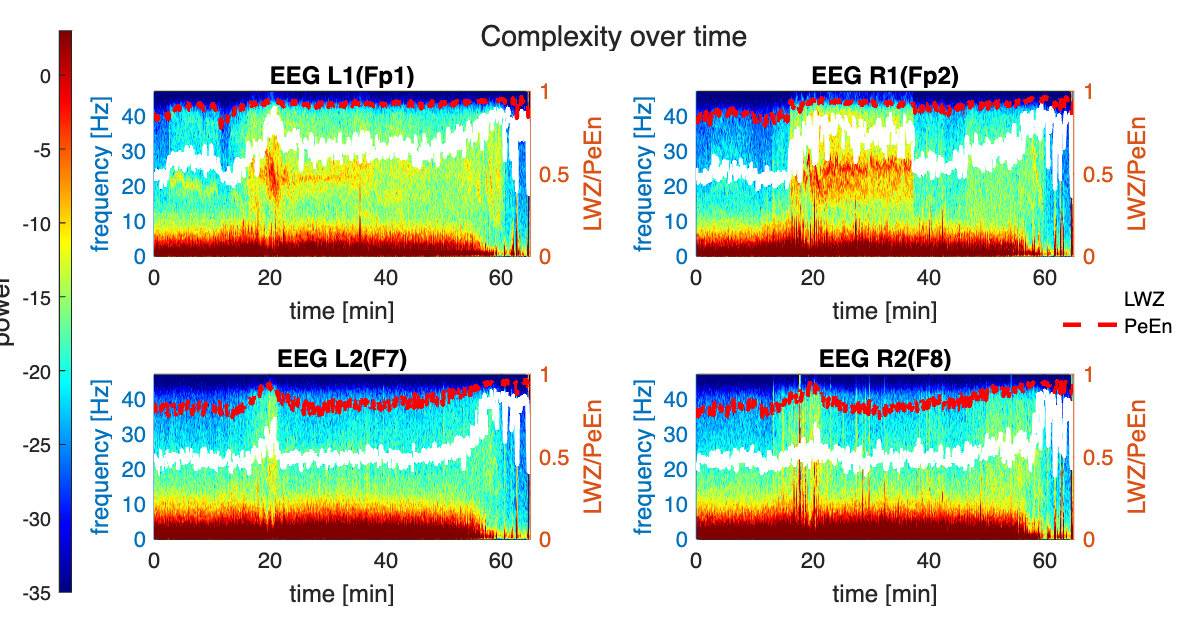


cb = colorbar('Position', [0.05 0.05 0.01 0.9]); % Adjust position as needed
cb.Label.String = 'power';
cb.Label.FontSize = 12;

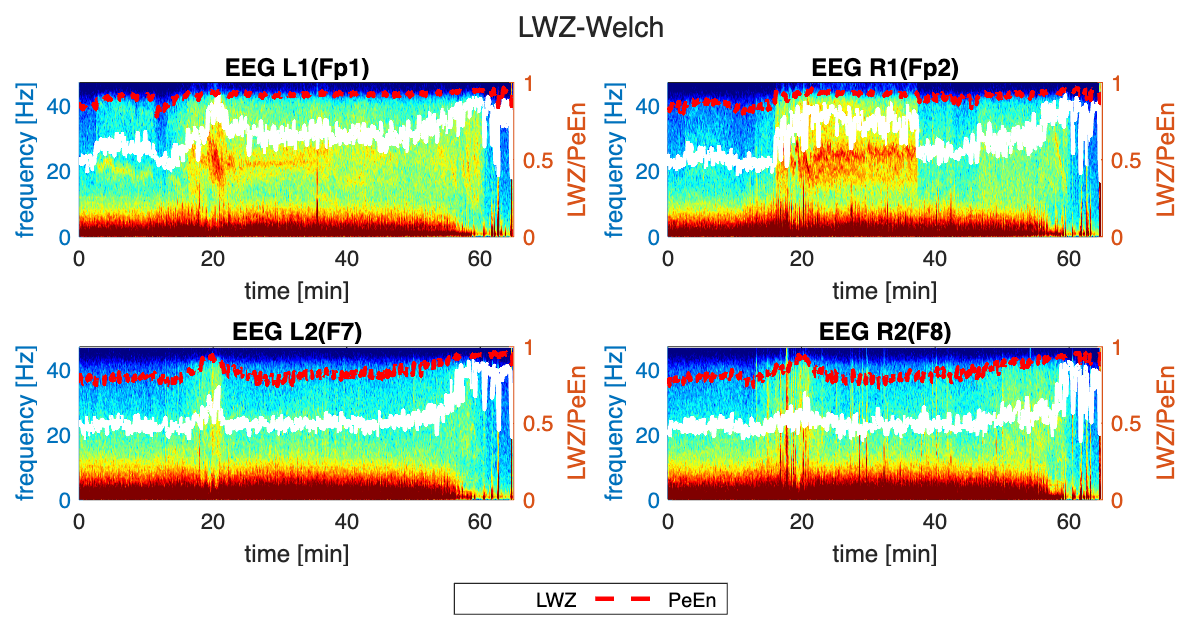


figure('Name','Parameters','Units','centimeters','Position', [0 0 19 10]);
tcl = tiledlayout(2,2);
% Adjust the layout to leave room for the legend
tcl.TileSpacing = 'compact';
tcl.Padding = 'compact';

sgtitle('LWZ-Welch')

% Initialize arrays to store line handles
h1_all = [];  % Handle for LWZ lines
h2_all = [];  % Handle for PeEn lines

for i = 1:4
    nexttile(i)
    title(EEG.chanlocs(i).labels)

    % Left Y-axis
    yyaxis left
    pcolor(tpsd, freq, 10*log10(PSD(:,:,i))); 
    clim([-35 3])
    ylabel('frequency [Hz]')
    xlabel('time [min]')
    colormap jet
    shading flat
    shading interp
    ylim([0 47])

    % Right Y-axis
    yyaxis right
    h1 = plot(tlwz, lwz(i,:), 'Color', 'w', 'LineWidth', 2);  % First line (LWZ)
    hold on
    h2 = plot(tpem, pem_EN(i,:), 'Color', 'r', 'LineWidth', 2);  % Second line (PeEn)
    hold off
    ylabel('LWZ/PeEn')
    ylim([0 1])

    % Store handles from the first subplot (or simply reuse them for legend)
    if i == 1
        h1_all = h1;
        h2_all = h2;
    end
end

% Create a legend for all the subplots, using the stored handles from the first subplot
lgd = legend([h1_all h2_all], {'LWZ', 'PeEn'}, 'Orientation', 'horizontal');
lgd.Layout.Tile = 'south';  % Place the legend at the bottom of the tiled layout

## ** BASELINE at Day 27**


clearvars -except EEG FOOOF_Results
clc
close all

baselineEEG = load("/Users/sebastianzinn/PowerFolders/Death_EEG/Enzephalopathie Tod/EDF_death/271022_Enzephalopathie_EEG.mat");

sr = 256;
fs=sr;
% Filter signal settings
low_cutoff = 1; % Low cut-off frequency for high-pass filter
high_cutoff = 45; % High cut-off frequency for low-pass filter

% Design the filters
[b_high, a_high] = butter(2, low_cutoff / (fs / 2), 'high');
[b_low, a_low] = butter(2, high_cutoff / (fs / 2), 'low');



clear buf
for i = 1:4
    buf = baselineEEG.EEG.data(i,:);
    buf = filtfilt(b_high, a_high, buf);
    buf = filtfilt(b_low, a_low, buf);
    baselineEEG.EEG.data(i,:) = buf;
    clear buf
end

tempeeg(1,:) = resample(baselineEEG.EEG.data(1,:),128,256); %Fp2-F8
tempeeg(2,:) = resample(baselineEEG.EEG.data(6,:),128,256); %Fp1-F7
tempeeg(3,:) = resample(baselineEEG.EEG.data(11,:),128,256); %Fp2-F4
tempeeg(4,:) = resample(baselineEEG.EEG.data(16,:),128,256); %Fp1-F3

[PSD(:,:,1), ~] = calculate_PSD_shift(tempeeg(1,:),128,256,10,5);
[PSD(:,:,2), ~] = calculate_PSD_shift(tempeeg(2,:),128,256,10,5);
[PSD(:,:,3), ~] = calculate_PSD_shift(tempeeg(3,:),128,256,10,5);
[PSD(:,:,4), freq] = calculate_PSD_shift(tempeeg(4,:),128,256,10,5);

bis(1,:) = openibis(tempeeg(1,:)');
bis(2,:) = openibis(tempeeg(2,:)');
bis(3,:) = openibis(tempeeg(3,:)');
bis(4,:) = openibis(tempeeg(4,:)');

tend = max(baselineEEG.EEG.times)/1000/60;
teeg = linspace(0,tend,length(tempeeg(1,:)));
tpsd = linspace(0,tend,length(PSD(1,:,1)));
tbis = linspace(0,tend,length(bis(1,:)));

locs = [EEG.chanlocs.labels];

Unable to resolve the name 'EEG.chanlocs.labels'.


fooof_settings = struct('peak_width_limits',[1,6],'max_n_peaks',3,'min_peak_height',0.3); 

for j = 1:4
    j
for i = 1:size(PSD,2) 
channel(j).fooof_results(i) = fooof(freq,PSD(:,i,j),[1 45],fooof_settings,1);
end
end

j = 1

j = 2

j = 3

j = 4


for j = 1:4
    j
    temp1 = [];
temp2 = [];
for i = 1:numel(channel(1).fooof_results)
    % Extract the aperiodic_params vector from the struct
    aperiodic_params_vector = channel(j).fooof_results(i).aperiodic_params;
    
    % Extract the first and second entries and append them to respective vectors
    temp1 = [temp1; aperiodic_params_vector(1)];
    temp2 = [temp2; aperiodic_params_vector(2)];
end
offset(:,j) = temp1;    
exponent(:,j) = temp2;
    
    clear temp1 temp2
end

j = 1

j = 2

j = 3

j = 4



FOOOF_Results.Exponent(33:36) = mean(exponent(:,:),1)';
FOOOF_Results.offset(33:36) = mean(offset(:,:),1)'

FOOOF_Results = 41×5 table
       Zeitpunkt        Category      Exponent     offset     Channel
    _______________    ___________    ________    ________    _______

    {'baseline'   }    {'death 0'}     2.4582       1.1517    {'Fp1'}
    {'baseline'   }    {'death 0'}      2.748       1.3235    {'Fp2'}
    {'baseline'   }    {'death 0'}     3.0235       1.8982    {'F7' }
    {'baseline'   }    {'death 0'}     3.0264       1.8839    {'F8' }
    {'minus 18min'}    {'death 1'}     2.0768       1.0196    {'Fp1'}
    {'minus 18min'}    {'death 1'}     1.7021      0.81567    {'Fp2'}
    {'minus 18min'}    {'death 1'}     2.8997       1.8141    {'F7' }
    {'minus 18min'}    {'death 1'}     2.9011       1.9056    {'F8' }
    {'minus 3min' }    {'death 2'}    0.84355     -0.85217    {'Fp1'}
    {'minus 3min' }    {'death 2

figure('Name','Parameters','Units','centimeters','Position', [0 0 19 10]);
tcl = tiledlayout(2,2);

sgtitle('openibis coma day 27')
for i = 1:4
nexttile(i)
title(EEG.chanlocs(i).labels)
yyaxis left
  pcolor(tpsd,freq,10*log10(PSD(:,:,i))); 
   clim([-35 3])
   ylabel 'frequency [Hz]'
   xlabel 'time [min]'
   colormap turbo
   shading flat
   shading interp
   ylim ([0 47])
yyaxis right
   plot(tbis,bis(i,:))
   ylabel 'openibis'
       ylim ([0 100])
end


figure('Name','Parameters','Units','centimeters','Position', [0 0 19 10]);
tcl = tiledlayout(2,2);

sgtitle('Exponent coma day 27')
for i = 1:4
nexttile(i)
title(EEG.chanlocs(i).labels)
yyaxis left
  pcolor(tpsd,freq,10*log10(PSD(:,:,i))); 
   clim([-35 3])
   ylabel 'frequency [Hz]'
   xlabel 'time [min]'
   colormap turbo
   shading flat
   shading interp
   ylim ([0 47])
yyaxis right
   plot(tpsd,exponent(:,i))
   ylabel 'exponent'
       ylim ([0 4])
end

figure('Name','Parameters','Units','centimeters','Position', [0 0 19 10]);
tcl = tiledlayout(2,2);

sgtitle('Offset coma day 27')
for i = 1:4
nexttile(i)
title(EEG.chanlocs(i).labels)
yyaxis left
  pcolor(tpsd,freq,10*log10(PSD(:,:,i))); 
   clim([-35 3])
   ylabel 'frequency [Hz]'
   xlabel 'time [min]'
   colormap jet
   shading flat
   shading interp
   ylim ([0 47])
yyaxis right
   plot(tpsd,offset(:,i),"Color","b")
   ylabel 'offset'
       ylim ([0 4])
end


## **Steady State Surgery**


clearvars -except EEG baselineEEG FOOOF_Results
clc
close all
load('/Users/sebastianzinn/PowerFolders/Death_EEG/Enzephalopathie Tod/Matlabfiles/Srdjan_FOOOF/Steadystate.mat')


for j = 1:2
    temp1 = [];
    temp2 = [];
    temp3 = [];
    temp4 = [];
            for i = 1:numel(results)
                if results(i).MainDrug == "Propofol"
    
                     % Extract the aperiodic_params vector from the struct
                    aperiodic_params_vector = results(i).fooof_results(j).aperiodic_params;
                    
                    % Extract the first and second entries and append them to respective vectors
                    temp1 = [temp1; aperiodic_params_vector(1)];
                    temp2 = [temp2; aperiodic_params_vector(2)]; 

                elseif results(i).MainDrug == "Sevoflurane"
    
                     % Extract the aperiodic_params vector from the struct
                    aperiodic_params_vector = results(i).fooof_results(j).aperiodic_params;
                    
                    % Extract the first and second entries and append them to respective vectors
                    temp3 = [temp3; aperiodic_params_vector(1)];
                    temp4 = [temp4; aperiodic_params_vector(2)]; 


                
                end
            end
    Propofol.offset(:,j) = temp1;    
    Propofol.exponent(:,j) = temp2;
    Sevoflurane.offset(:,j) = temp3;
    Sevoflurane.exponent(:,j) = temp4;

    clear temp1 temp2 temp3 temp4
end 



%groups
g1 = repmat({'Propofol'},size(Propofol.exponent,1),1);
g2 = repmat({'Sevoflurane'},size(Sevoflurane.exponent,1),1);
g = [g1; g2];

exponents = [Propofol.exponent(:,1);Sevoflurane.exponent(:,1)];
offsets = [Propofol.offset(:,1);Sevoflurane.offset(:,1)];

figure()
tcl = tiledlayout(2,1);
nexttile()
boxplot(exponents,g)
title('Exponent')
ylim([0 4])
nexttile()
boxplot(offsets,g)
title('Offset')
ylim([0 4])


%Random 5 Propofol values 
FOOOF_Results.Exponent(23:27) = exponents(23:27);
FOOOF_Results.offset(23:27) = offsets(23:27);

FOOOF_Results.Exponent(28:32) = exponents(60:64);
FOOOF_Results.offset(28:32) = offsets(60:64);

function [PSD, freq]= calculate_PSD_shift(EEG, fs, NFFT, windowlength, shift)

% calculate_PSD calculates the PSD of the input signal
% EEG:          input signal
% fhighpass:    highpass cutoff in Hz
% fs:           sample rate
% windowlength: window in s the power is calculated over
% shift:        shift in s:
% PSD:          power spectral density matrix
% frequency_resolution: freq info

%h = waitbar(0,'Progress of PSD calculation');
%NFFT=128;
    cnt =1;
    for a=1:fs*shift:length(EEG)-windowlength*fs
        start = a;
        stop = a+windowlength*fs-1;
        
        if sum(isnan(EEG(start:stop))) > 0
           freq = 0:fs/NFFT:fs/2;
           BUF2 = NaN(1,length(freq));
        else 
           [BUF2, freq] = pwelch(EEG(start:stop),[],[],NFFT,fs,'onesided');
        end
        
        PSD(:,cnt)=(BUF2);
        
        clear BUF BUF2
        cnt = cnt+1;
    end     
end


## **Stady State Awake - closed eye**


clearvars -except FOOOF_Results EEG_REM EEG_N3 EEG EEG_wake EEG_filtered
clc
close all
load("/Users/sebastianzinn/PowerFolders/Death_EEG/Enzephalopathie Tod/Matlabfiles/Wake_EEG_II.mat")


% Define the sampling frequency and the cutoff frequencies
Fs = 512;                   % Sampling frequency in Hz
LowCutoff = 0.5;              % Lower cutoff frequency in Hz
HighCutoff = 45;            % Upper cutoff frequency in Hz

% Design a bandpass filter using the designfilt function
d = designfilt('bandpassiir', 'FilterOrder', 4, ...
               'HalfPowerFrequency1', LowCutoff, 'HalfPowerFrequency2', HighCutoff, ...
               'SampleRate', Fs);

% Load or define your 5-channel EEG data matrix (e.g., EEG_data)
% EEG_data should be a matrix of size [5, N] where 5 is the number of channels and N is the number of samples
% For example, EEG_data = randn(5, 1000);  % Random data for demonstration

% Initialize the filtered EEG data matrix
EEG_filtered = zeros(size(EEG_wake));

% Apply the bandpass filter to each channel of EEG data
for channel = 1:size(EEG_wake, 1)
    EEG_filtered(channel, 30721:end) = filtfilt(d, EEG_wake(channel, 30721:end));
end
clear channel

EEG = EEG_wake;
tempeeg(1,:) = resample(EEG(7,30721:end),128,512);
tempeeg(2,:) = resample(EEG(8,30721:end),128,512);
tempeeg(3,:) = resample(EEG(9,30721:end),128,512);
tempeeg(4,:) = resample(EEG(10,30721:end),128,512);
tempeeg(5,:) = resample(EEG(11,30721:end),128,512);

[PSD(:,:,1), ~] = calculate_PSD_shift(tempeeg(1,:),128,256,20,10);
[PSD(:,:,2), ~] = calculate_PSD_shift(tempeeg(2,:),128,256,20,10);
[PSD(:,:,3), ~] = calculate_PSD_shift(tempeeg(3,:),128,256,20,10);
[PSD(:,:,4), ~] = calculate_PSD_shift(tempeeg(4,:),128,256,20,10);
[PSD(:,:,5), freq] = calculate_PSD_shift(tempeeg(5,:),128,256,20,10);

bis(1,:) = openibis(tempeeg(1,:)');
bis(2,:) = openibis(tempeeg(2,:)');
bis(3,:) = openibis(tempeeg(3,:)');
bis(4,:) = openibis(tempeeg(4,:)');
bis(5,:) = openibis(tempeeg(5,:)');

tend = 2/1000/60
teeg = linspace(0,tend,length(tempeeg(1,:)));
tpsd = linspace(0,tend,length(PSD(1,:,1)));
tbis = linspace(0,tend,length(bis(1,:)));

locs = 'wake';


fooof_settings = struct('peak_width_limits',[1,6],'max_n_peaks',3,'min_peak_height',0.3); 

for j = 1:5
    j;
    if isnan(PSD(:,:,j))
        continue
    else
for i = 1:size(PSD,2) 
channel(j).fooof_results(i) = fooof(freq,PSD(:,i,j),[1 40],fooof_settings,1);
end
    end
end




for j = 1:5
    j
    if isnan(PSD(:,:,j))
        continue
    else
    temp1 = [];
temp2 = [];
for i = 1:numel(channel(1).fooof_results)
    % Extract the aperiodic_params vector from the struct
    aperiodic_params_vector = channel(j).fooof_results(i).aperiodic_params;
    
    % Extract the first and second entries and append them to respective vectors
    temp1 = [temp1; aperiodic_params_vector(1)];
    temp2 = [temp2; aperiodic_params_vector(2)];
end
offset(:,j) = temp1;    
exponent(:,j) = temp2;
    
    clear temp1 temp2
    end
end


FOOOF_Results.Exponent(37:41) = mean(exponent(:,:),1)';
FOOOF_Results.offset(37:41) = mean(offset(:,:),1)';

writetable(FOOOF_Results, '/Users/sebastianzinn/PowerFolders/Death_EEG/Enzephalopathie Tod/Matlabfiles/FOOF_sumery3.csv');

figure('Name','Parameters','Units','centimeters','Position', [0 0 19 10]);
tcl = tiledlayout(2,3);

sgtitle('openibis')
for i = 1:5
    if isnan(PSD(:,:,j))
        continue
    else
nexttile(i)
title('Wake',num2str(i))
yyaxis left
  pcolor(tpsd,freq,10*log10(PSD(:,:,i))); 
   clim([-35 3])
   ylabel 'frequency [Hz]'
   xlabel 'time [min]'
   colormap jet
   shading flat
   shading interp
   ylim ([-5 20])
yyaxis right
   plot(tbis,bis(i,:))
   ylabel 'openibis'
       ylim ([0 100])
    end
end



figure('Name','Parameters','Units','centimeters','Position', [0 0 19 10]);
tcl = tiledlayout(2,3);

sgtitle('Exponent')
for i = 1:5
    if isnan(PSD(:,:,j))
        continue
    else
nexttile(i)
title('Wake',num2str(i))
yyaxis left
  pcolor(tpsd,freq,10*log10(PSD(:,:,i))); 
   clim([-35 3])
   ylabel 'frequency [Hz]'
   xlabel 'time [min]'
   colormap turbo
   shading flat
   shading interp
   ylim ([0 47])
yyaxis right
   plot(tpsd,exponent(:,i))
   ylabel 'exponent'
       ylim ([0 4])
    end
end
   

figure('Name','Parameters','Units','centimeters','Position', [0 0 19 10]);
tcl = tiledlayout(2,3);

sgtitle('Offset')
for i = 1:5
    if isnan(PSD(:,:,j))
        continue
    else
nexttile(i)
title('wake',num2str(i))
yyaxis left
  pcolor(tpsd,freq,10*log10(PSD(:,:,i))); 
   clim([-35 3])
   ylabel 'frequency [Hz]'
   xlabel 'time [min]'
   colormap turbo
   shading flat
   shading interp
   ylim ([0 47])
yyaxis right
   plot(tpsd,offset(:,i))
   ylabel 'offset'
       ylim ([0 4])
    end
end


## Sleep Stage N2 & REM

### N2

clearvars -except FOOOF_Results EEG_REM EEG_N3
clc
close all
load("/Users/sebastianzinn/PowerFolders/Death_EEG/Enzephalopathie Tod/Matlabfiles/Sleep_EEGs/N2_REM_Periods.mat")



% Filter the signal 
sr = 256;
fs=sr;
% Filter signal settings
low_cutoff = 1; % Low cut-off frequency for high-pass filter
high_cutoff = 45; % High cut-off frequency for low-pass filter

% Design the filters
[b_high, a_high] = butter(2, low_cutoff / (fs / 2), 'high');
[b_low, a_low] = butter(2, high_cutoff / (fs / 2), 'low');



clear buf
for i = 1:4
    buf = EEG_N3(:,3,i);
    buf = filtfilt(b_high, a_high, buf);
    buf = filtfilt(b_low, a_low, buf);
    EEG_N3(:,3,i) = buf;
    clear buf
end

clear buf
for i = 1:4
    buf = EEG_REM(:,3,i);
    buf = filtfilt(b_high, a_high, buf);
    buf = filtfilt(b_low, a_low, buf);
    EEG_REM(:,3,i) = buf;
    clear buf
end


tempeeg(1,:) = resample(EEG_N3(:,3,1)',128,256);
tempeeg(2,:) = resample(EEG_N3(:,3,2)',128,256);
tempeeg(3,:) = resample(EEG_N3(:,3,3)',128,256);
tempeeg(4,:) = resample(EEG_N3(:,3,4)',128,256);
tempeeg(5,:) = resample(EEG_N3(:,3,5)',128,256);

[PSD(:,:,1), ~] = calculate_PSD_shift(tempeeg(1,:),128,256,10,5);
[PSD(:,:,2), ~] = calculate_PSD_shift(tempeeg(2,:),128,256,10,5);
[PSD(:,:,3), ~] = calculate_PSD_shift(tempeeg(3,:),128,256,10,5);
[PSD(:,:,4), ~] = calculate_PSD_shift(tempeeg(4,:),128,256,10,5);
[PSD(:,:,5), freq] = calculate_PSD_shift(tempeeg(5,:),128,256,10,5);

bis(1,:) = openibis(tempeeg(1,:)');
bis(2,:) = openibis(tempeeg(2,:)');
bis(3,:) = openibis(tempeeg(3,:)');
bis(4,:) = openibis(tempeeg(4,:)');
bis(5,:) = openibis(tempeeg(5,:)');

tend = 2/1000/60
teeg = linspace(0,tend,length(tempeeg(1,:)));
tpsd = linspace(0,tend,length(PSD(1,:,1)));
tbis = linspace(0,tend,length(bis(1,:)));

locs = 'N3';


fooof_settings = struct('peak_width_limits',[1,6],'max_n_peaks',3,'min_peak_height',0.3); 

for j = 1:5
    j
    if isnan(PSD(:,:,j))
        continue
    else
for i = 1:size(PSD,2) 
channel(j).fooof_results(i) = fooof(freq,PSD(:,i,j),[1 47],fooof_settings,1);
end
    end
end




for j = 1:5
    j
    if isnan(PSD(:,:,j))
        continue
    else
    temp1 = [];
temp2 = [];
for i = 1:numel(channel(1).fooof_results)
    % Extract the aperiodic_params vector from the struct
    aperiodic_params_vector = channel(j).fooof_results(i).aperiodic_params;
    
    % Extract the first and second entries and append them to respective vectors
    temp1 = [temp1; aperiodic_params_vector(1)];
    temp2 = [temp2; aperiodic_params_vector(2)];
end
offset(:,j) = temp1;    
exponent(:,j) = temp2;
    
    clear temp1 temp2
    end
end


FOOOF_Results.Exponent(13:17) = median(exponent(:,:),1)';
FOOOF_Results.offset(13:17) = median(offset(:,:),1)';

figure('Name','Parameters','Units','centimeters','Position', [0 0 19 10]);
tcl = tiledlayout(2,3);

sgtitle('openibis')
for i = 1:5
    if isnan(PSD(:,:,j))
        continue
    else
nexttile(i)
title('Sleep N3',num2str(i))
yyaxis left
  pcolor(tpsd,freq,10*log10(PSD(:,:,i))); 
   clim([-35 3])
   ylabel 'frequency [Hz]'
   xlabel 'time [min]'
   colormap turbo
   shading flat
   shading interp
   ylim ([0 47])
yyaxis right
   plot(tbis,bis(i,:))
   ylabel 'openibis'
       ylim ([0 100])
    end
end



figure('Name','Parameters','Units','centimeters','Position', [0 0 19 10]);
tcl = tiledlayout(2,3);

sgtitle('Exponent')
for i = 1:5
    if isnan(PSD(:,:,j))
        continue
    else
nexttile(i)
title('Sleep N3',num2str(i))
yyaxis left
  pcolor(tpsd,freq,10*log10(PSD(:,:,i))); 
   clim([-35 3])
   ylabel 'frequency [Hz]'
   xlabel 'time [min]'
   colormap turbo
   shading flat
   shading interp
   ylim ([0 47])
yyaxis right
   plot(tpsd,exponent(:,i))
   ylabel 'exponent'
       ylim ([0 4])
    end
end
   

figure('Name','Parameters','Units','centimeters','Position', [0 0 19 10]);
tcl = tiledlayout(2,3);

sgtitle('Offset')
for i = 1:5
    if isnan(PSD(:,:,j))
        continue
    else
nexttile(i)
title('Sleep N3',num2str(i))
yyaxis left
  pcolor(tpsd,freq,10*log10(PSD(:,:,i))); 
   clim([-35 3])
   ylabel 'frequency [Hz]'
   xlabel 'time [min]'
   colormap turbo
   shading flat
   shading interp
   ylim ([0 47])
yyaxis right
   plot(tpsd,offset(:,i))
   ylabel 'offset'
       ylim ([0 4])
    end
end


## REM Sleep

clearvars -except FOOOF_Results
clc
close all
load("/Users/sebastianzinn/PowerFolders/Death_EEG/Enzephalopathie Tod/Matlabfiles/Sleep_EEGs/N2_REM_Periods.mat")

%%
        


tempeeg(1,:) = resample(EEG_REM(:,3,1)',128,256);
tempeeg(2,:) = resample(EEG_REM(:,3,2)',128,256);
tempeeg(3,:) = resample(EEG_REM(:,3,3)',128,256);
tempeeg(4,:) = resample(EEG_REM(:,3,4)',128,256);
tempeeg(5,:) = resample(EEG_REM(:,3,5)',128,256);

[PSD(:,:,1), ~] = calculate_PSD_shift(tempeeg(1,:),128,256,10,5);
[PSD(:,:,2), ~] = calculate_PSD_shift(tempeeg(2,:),128,256,10,5);
[PSD(:,:,3), ~] = calculate_PSD_shift(tempeeg(3,:),128,256,10,5);
[PSD(:,:,4), ~] = calculate_PSD_shift(tempeeg(4,:),128,256,10,5);
[PSD(:,:,5), freq] = calculate_PSD_shift(tempeeg(5,:),128,256,10,5);

bis(1,:) = openibis(tempeeg(1,:)');
bis(2,:) = openibis(tempeeg(2,:)');
bis(3,:) = openibis(tempeeg(3,:)');
bis(4,:) = openibis(tempeeg(4,:)');
bis(5,:) = openibis(tempeeg(5,:)');

tend = 2/1000/60
teeg = linspace(0,tend,length(tempeeg(1,:)));
tpsd = linspace(0,tend,length(PSD(1,:,1)));
tbis = linspace(0,tend,length(bis(1,:)));

locs = 'N3';


fooof_settings = struct('peak_width_limits',[1,6],'max_n_peaks',3,'min_peak_height',0.3); 

for j = 1:5
    j
    if isnan(PSD(:,:,j))
        continue
    else
for i = 1:size(PSD,2) 
channel(j).fooof_results(i) = fooof(freq,PSD(:,i,j),[1 47],fooof_settings,1);
end
    end
end




for j = 1:5
    j
    if isnan(PSD(:,:,j))
        continue
    else
    temp1 = [];
temp2 = [];
for i = 1:numel(channel(1).fooof_results)
    % Extract the aperiodic_params vector from the struct
    aperiodic_params_vector = channel(j).fooof_results(i).aperiodic_params;
    
    % Extract the first and second entries and append them to respective vectors
    temp1 = [temp1; aperiodic_params_vector(1)];
    temp2 = [temp2; aperiodic_params_vector(2)];
end
offset(:,j) = temp1;    
exponent(:,j) = temp2;
    
    clear temp1 temp2
    end
end

FOOOF_Results.Exponent(18:22) = median(exponent(:,:),1)';
FOOOF_Results.offset(18:22) = median(offset(:,:),1)';

writetable(FOOOF_Results, '/Users/sebastianzinn/PowerFolders/Death_EEG/Enzephalopathie Tod/Matlabfiles/FOOF_sumery3.csv');

figure('Name','Parameters','Units','centimeters','Position', [0 0 19 10]);
tcl = tiledlayout(2,3);

sgtitle('openibis')
for i = 1:5
    if isnan(PSD(:,:,j))
        continue
    else
nexttile(i)
title('Sleep REM',num2str(i))
yyaxis left
  pcolor(tpsd,freq,10*log10(PSD(:,:,i))); 
   clim([-35 3])
   ylabel 'frequency [Hz]'
   xlabel 'time [min]'
   colormap turbo
   shading flat
   shading interp
   ylim ([0 47])
yyaxis right
   plot(tbis,bis(i,:))
   ylabel 'openibis'
       ylim ([0 100])
    end
end



figure('Name','Parameters','Units','centimeters','Position', [0 0 19 10]);
tcl = tiledlayout(2,3);

sgtitle('Exponent')
for i = 1:5
    if isnan(PSD(:,:,j))
        continue
    else
nexttile(i)
title('Sleep REM',num2str(i))
yyaxis left
  pcolor(tpsd,freq,10*log10(PSD(:,:,i))); 
   clim([-35 3])
   ylabel 'frequency [Hz]'
   xlabel 'time [min]'
   colormap turbo
   shading flat
   shading interp
   ylim ([0 47])
yyaxis right
   plot(tpsd,exponent(:,i))
   ylabel 'exponent'
       ylim ([0 4])
    end
end
   

figure('Name','Parameters','Units','centimeters','Position', [0 0 19 10]);
tcl = tiledlayout(2,3);

sgtitle('Offset')
for i = 1:5
    if isnan(PSD(:,:,j))
        continue
    else
nexttile(i)
title('Sleep REM',num2str(i))
yyaxis left
  pcolor(tpsd,freq,10*log10(PSD(:,:,i))); 
   clim([-35 3])
   ylabel 'frequency [Hz]'
   xlabel 'time [min]'
   colormap turbo
   shading flat
   shading interp
   ylim ([0 47])
yyaxis right
   plot(tpsd,offset(:,i))
   ylabel 'offset'
       ylim ([0 4])
    end
end

